2.2.1

create and displays 2d signals 

a.

i1 = signal(256,256,200,5,0,50);
i2 = signal(256,256,200,0,10,100);
i3 = signal(256,256,200,5,10,127);

b.

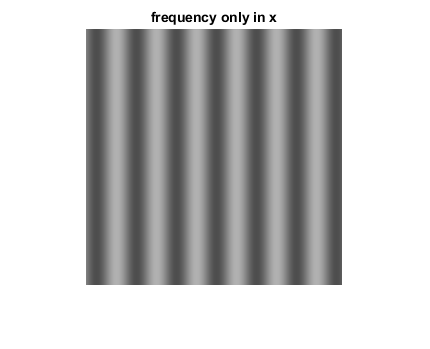

figure;
imshow(uint8(i1));
title('frequency only in x');

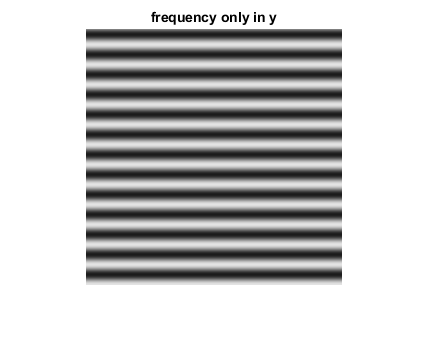


figure;
imshow(uint8(i2));
title('frequency only in y');

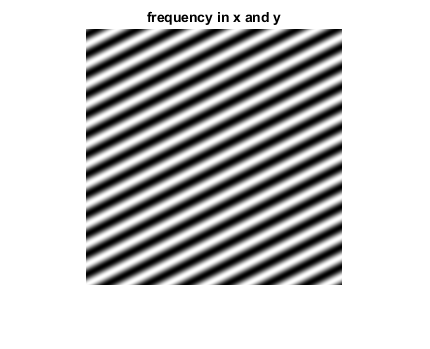


figure;
imshow(uint8(i3));
title('frequency in x and y');

c.

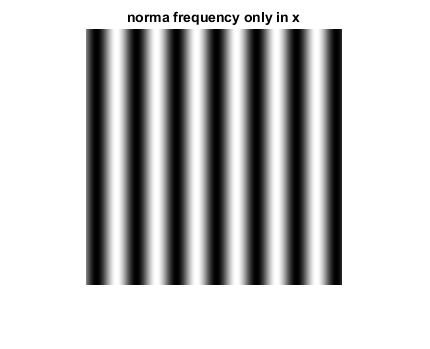

figure;
imshow(uint8(i1),[]);
title('norma frequency only in x');

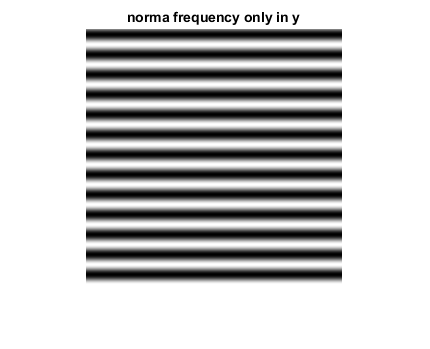


figure;
imshow(uint8(i2),[]);
title('norma frequency only in y');

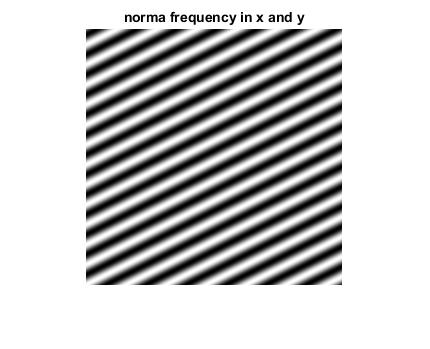


figure;
imshow(uint8(i3),[]);
title('norma frequency in x and y');

d.

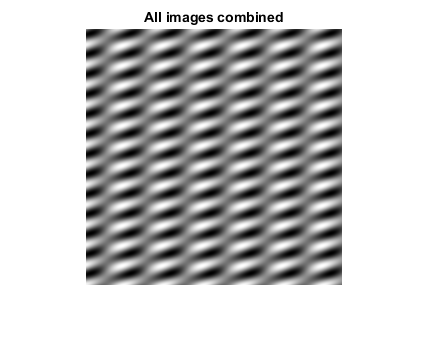


i4 = normImg(i1 + i2 + i3);

figure;
imshow(uint8(i4),[]);
title('All images combined');

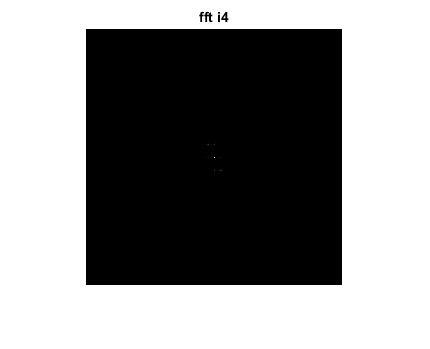


figure;
imshow(fftshift(abs(fft2(i4))),[]);
title('fft i4');

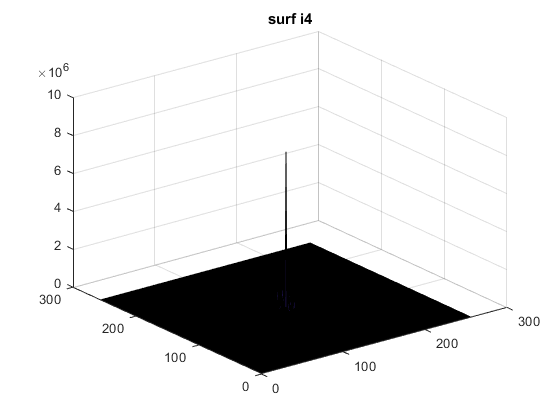


figure;
surf(fftshift(abs(fft2(i4))));
title('surf i4');

i4 contains all of the sub signals, it is hard to tell from the image but in the frequency domain we can see that all of the sub signals frequencys are present.

2.2.2

cambel-robson chart

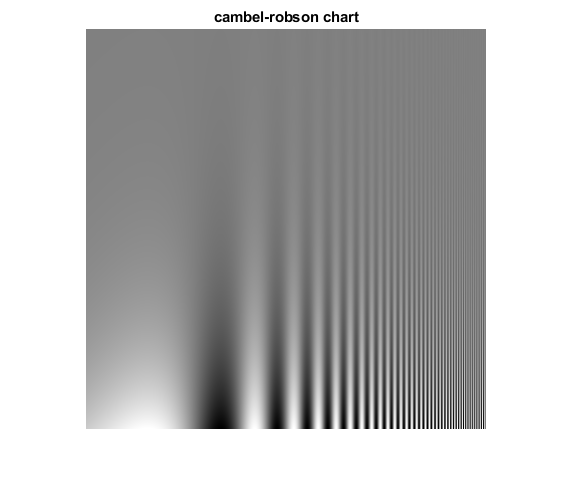

min_freq = 0.1; % cycles per image
N=400;
min_amplitude = 1;
max_amplitude = 127;
max_freq = 40; % cycles per image
f_vect = linspace(log(min_freq), log(max_freq), N);
f = exp(f_vect);
a_vect = linspace(log(min_amplitude), log(max_amplitude), N);
a = exp(a_vect);
img = 128 + a' * sin(2 * pi * f);

figure;
imshow(img,[])
title('cambel-robson chart');

2.3.2

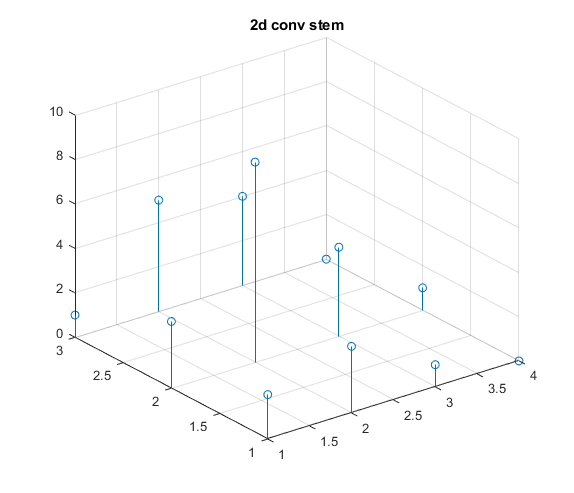

h= [1 0; 1 1];
f=[2 3 1; 1 4 0];
g=conv2(h,f); 
stem3(g)
title('2d conv stem')

2.3.2.2

a.

f=[2 3 1; 1 4 0];
h= [1 0 0 1 0 0 1; 0 0 0 0 0 0 0; 1 0 0 1 0 0 1; 0 0 0 0 0 0 0; 1 0 0 1 0 0 1; 0 0 0 0 0 0 0; 1 0 0 1 0 0 1];
g=conv2(h,f) ;


b.

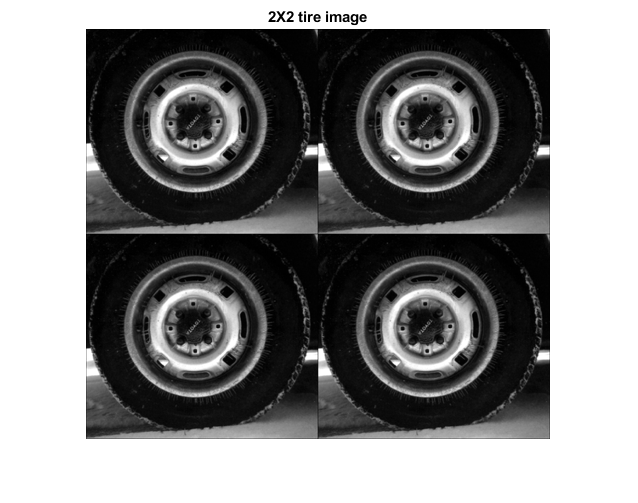

%addpath("D:\Program Files\MATLAB\R2018a\toolbox\images\imdata");
p=imread('tire.tif');
[m,n] = size(p);


h = zeros(m+1, n+1);
h(1,1) = 1;
h(1,end) = 1;
h(end , 1) = 1;
h(end,end) = 1;

g=conv2(h,p);
imshow(g,[])
title('2X2 tire image')

c.

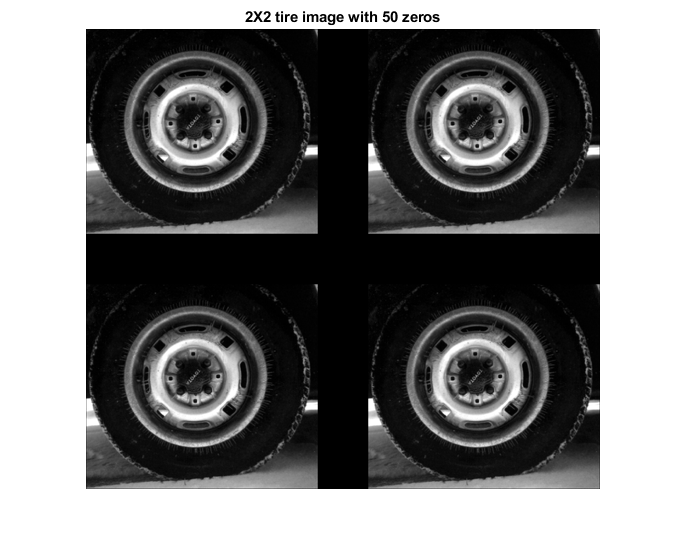

h = zeros(m+51, n+51);
h(1,1) = 1;
h(1,end) = 1;
h(end , 1) = 1;
h(end,end) = 1;

g=conv2(h,p);
imshow(g,[])
title('2X2 tire image with 50 zeros')

2.3.3.3.1

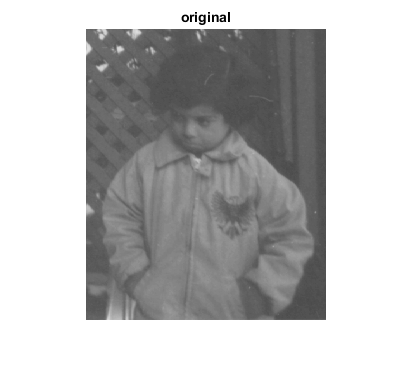

%addpath("D:\Program Files\MATLAB\R2018a\toolbox\images\imdata");
p=imread('pout.tif');

figure;
imshow(p)
title('original');

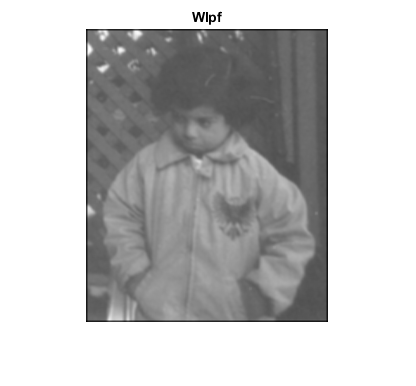


figure;
Wlpf = 1/9*ones(3);
g = conv2(Wlpf,p);
imshow(g,[])
title('Wlpf');

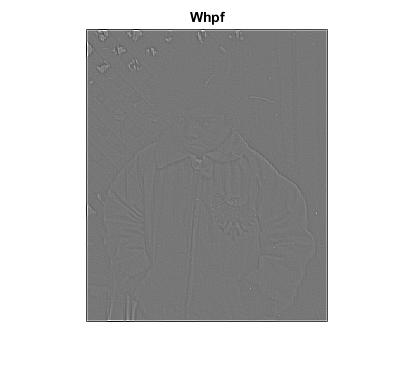


figure;
Whpf = -1/9*ones(3);
Whpf(2,2) = 8/9;
g = conv2(Whpf,p);
imshow(g,[])
title('Whpf');

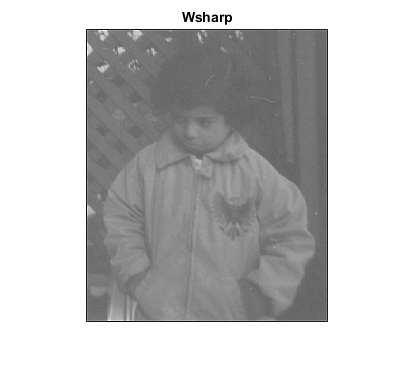


figure;
Wsharp = -1/9*ones(3);
Wsharp(2,2) = 17/9;
g = conv2(Wsharp,p);
imshow(g,[])
title('Wsharp');

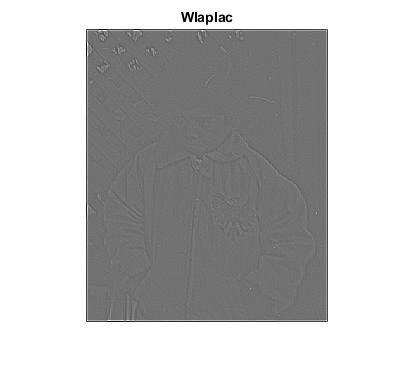


figure;
Wlaplac = [0 -1 0; -1 4 -1; 0 -1 0];
g = conv2(Wlaplac,p);
imshow(g,[])
title('Wlaplac');

2.3.3.3.2

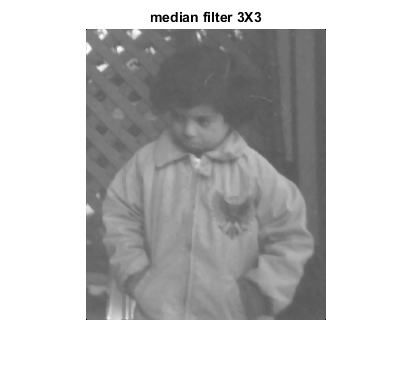

g = medfilt2(p);
figure;
imshow(g,[]);
title('median filter 3X3')

median with loop: 

m = size(p,2)

m = 240

n = size(p,1)

n = 291

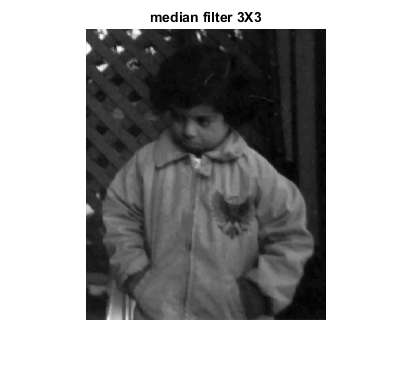

temp = p;
for c = 1: n
    for r=1:m
        minc = max([1, c-1]);
        minr = max([1, r-1]);
        maxc = min([n, c+1]);
        maxr = min([m, r+1]);
        submat = p(minc:maxc,minr:maxr);
        temp(c,r) = median(median(submat));
    end
end
figure;
imshow(temp,[]);
title('median filter 3X3')

2.3.3.4.1

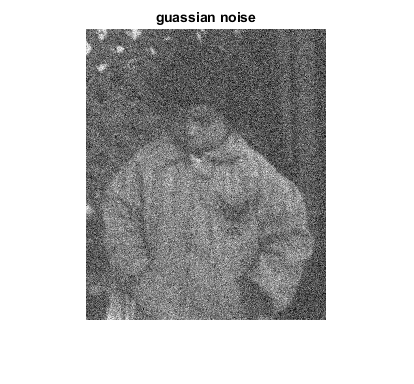

pn = imnoise(p,'gaussian', 0, 0.01);

figure;
imshow(pn,[]);
title('guassian noise');

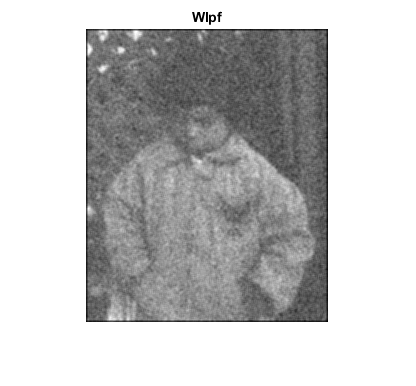

gWlpf = conv2(Wlpf,pn);

figure;
imshow(gWlpf,[])
title('Wlpf');

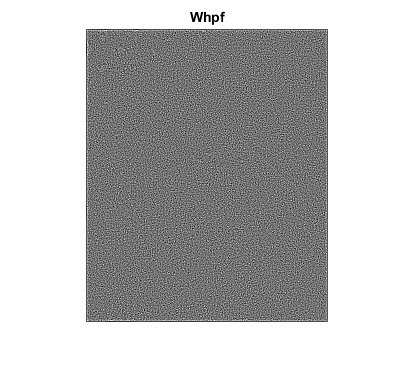


gWhpf = conv2(Whpf,pn);

figure;
imshow(gWhpf,[])
title('Whpf');

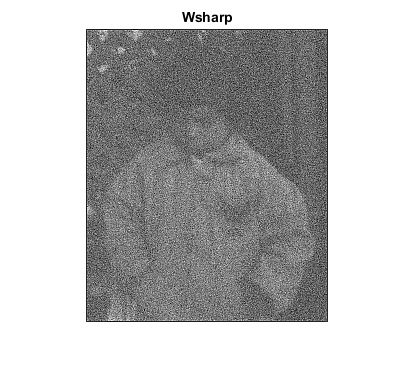


figure;
gWsharp = conv2(Wsharp,pn);
imshow(gWsharp,[])
title('Wsharp');

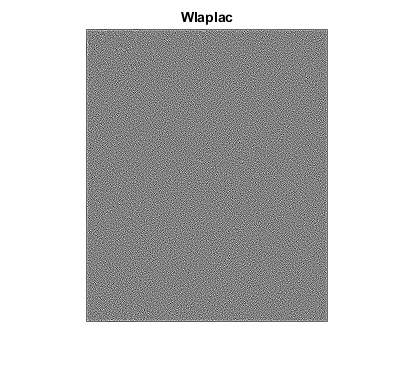


figure;
gWlaplac = conv2(Wlaplac,pn);
imshow(gWlaplac,[])
title('Wlaplac');

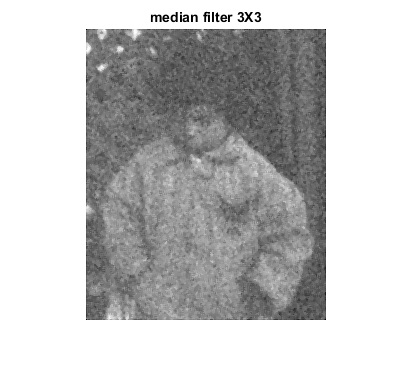


gmedfilt2 = medfilt2(pn);
figure;
imshow(gmedfilt2,[]);
title('median filter 3X3')

2.3.3.4.3

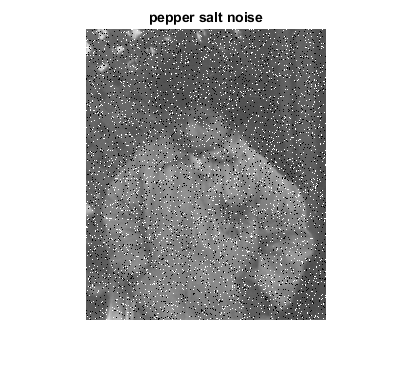

pn_sp = imnoise(p,'salt & pepper', 0.1);

figure;
imshow(pn_sp,[]);
title('pepper salt noise');

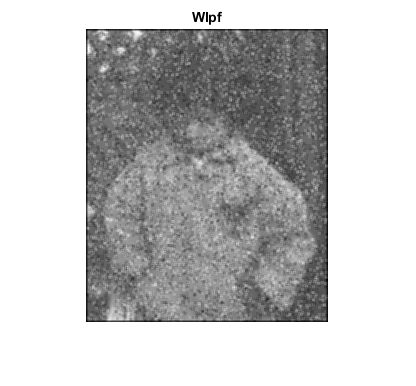


gWlpf_sp = conv2(Wlpf,pn_sp);

figure;
imshow(gWlpf_sp,[])
title('Wlpf');

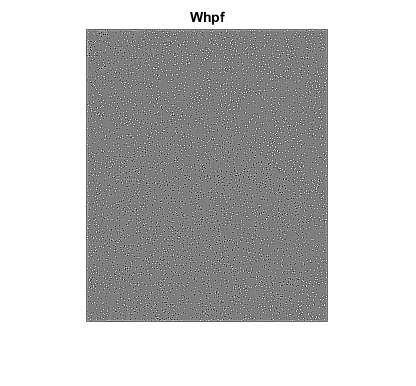


gWhpf_sp = conv2(Whpf,pn_sp);

figure;
imshow(gWhpf_sp,[])
title('Whpf');

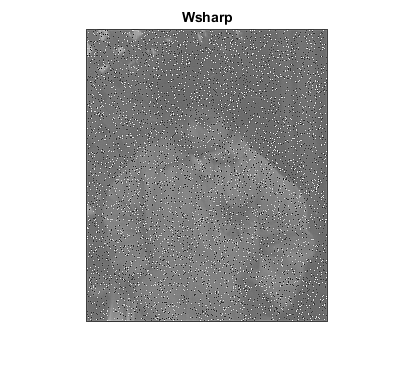


figure;
gWsharp_sp = conv2(Wsharp,pn_sp);
imshow(gWsharp_sp,[])
title('Wsharp');

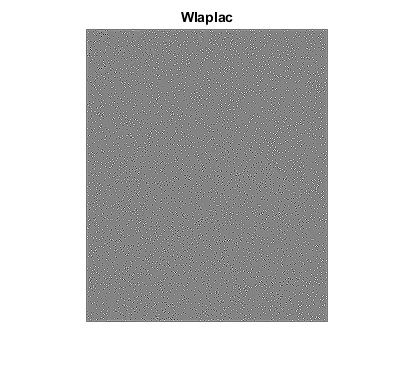


figure;
gWlaplac_sp = conv2(Wlaplac,pn_sp);
imshow(gWlaplac_sp,[])
title('Wlaplac');

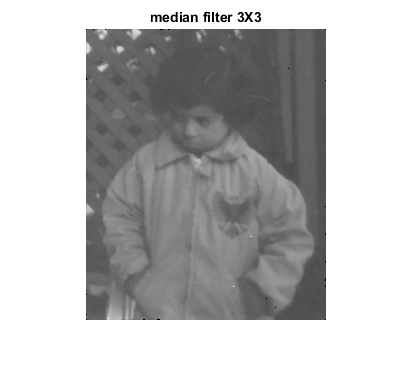


gmedfilt2_sp = medfilt2(pn_sp);
figure;
imshow(gmedfilt2_sp,[]);
title('median filter 3X3')

for gaussian noise the best filter is lpf and after sharp

for salt and pepper median  is the best filter

2.3.3.4.2 

calculate MSE:

M = size(p,1)

M = 291

N = size(p,2)

N = 240

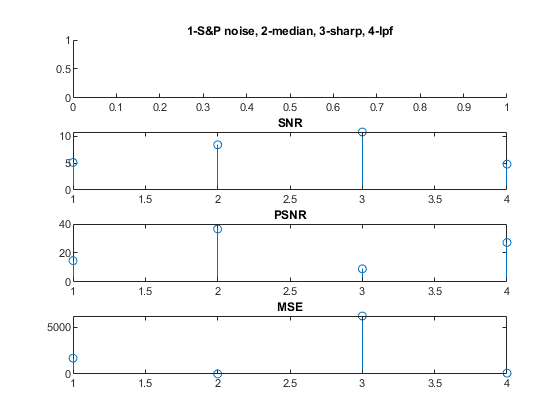

 
 snr_log = zeros(1,4);
 psnr_log = zeros(1,4);
 currect_mse = zeros(1,4);
 
 [snr_log(1), psnr_log(1), currect_mse(1)] = snrPsnrMse(p,pn_sp);
 [snr_log(2), psnr_log(2), currect_mse(2)] = snrPsnrMse(p,gmedfilt2_sp);
 [snr_log(3), psnr_log(3), currect_mse(3)]  = snrPsnrMse(p,double(gWsharp_sp));
 [snr_log(4), psnr_log(4), currect_mse(4)]  = snrPsnrMse(p,double(gWlpf));
 figure 
 subplot(4,1,1)
 title("1-S&P noise, 2-median, 3-sharp, 4-lpf")
 
 subplot(4,1,2)
 stem(abs(snr_log))
 title("SNR")
 
 subplot(4,1,3)
 stem(abs(psnr_log))
 title("PSNR")
 
  subplot(4,1,4)
 stem(abs(currect_mse))
 title("MSE")

functions

function [snr_log, psnr_log, currect_mse] = snrPsnrMse(p,pn)
    if size(p) < size(pn)
        pn = pn(2:size(p,1)+1,2:size(p,2)+1);
    end
    p = double(p);
    pn = double(pn);
    reference_max = max(max(p));
    reference_variance = vari(p);
    noise = pn - p;
    noise_var = vari(noise);
    snr_log = 10*log10(reference_variance / noise_var );
    currect_mse = mse(p, pn);
    psnr_log = 10*log10((reference_max)^2 / currect_mse);
    
end

function reference_variance = vari(reference_img)
    reference_img_f = reshape(reference_img,[],1);
    reference_avg = mean(reference_img_f);
    reference_variance = sum((reference_img - reference_avg).^2 / (size(reference_img,1) * size(reference_img,2)));
end

function MSE = mse(p,pn)
    M = size(p,1);
    N = size(p,2);
    MSE =sum(sum((p-pn).^2)) / (M*N);
end


function img = signal(w,h,fs,fx,fy,amp)
        Ts = 1/fs;
        sx = [0:1:w-1];
        sy = [0:1:h-1]';
        wx = 2 * pi * fx * Ts;
        wy = 2 * pi * fy * Ts;        
        img =  127 -  amp * sin(wy * sy + wx * sx);
end

function norm = normImg(img)
    norm = 255*(img - min(img(:)))/(max(img(:) - min(img(:))));
end
